# Taylor Polynomials: An Application of Derivatives to Approximating Functions

Consider a smooth function $f(x)$, such that it has as many derivatives as we wish to compute. We can approximate this near a point $x_0$.

syms F(x) f(x)
F(x) = cos(x);
x0 =  pi/2;
 

With a constant function, the best approximation is simply $P_0 = f(x_0)$.

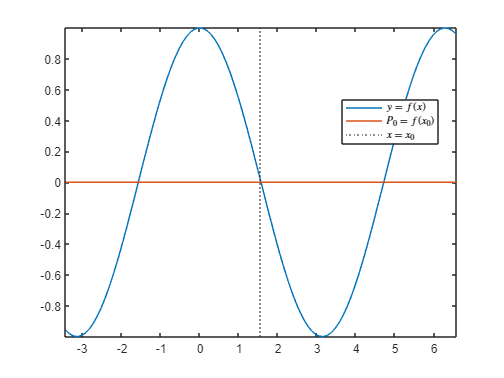

xval = x0-5:.1:x0+5;
clf
plot(xval,F(xval))
hold on
plot([xval(1) xval(end)],[F(x0) F(x0)])
xline(x0,":")
hold off
legend(["$y=f(x)$" "$P_0=f(x_0)$" "$x=x_0$"],"Interpreter","latex","Location","best")
axis tight

## Tangent Lines

The best linear approximation to a differentiable function at a point is the tangent line at that point. Continuing with 

fexp = F(x);
displayFormula("f(x) = fexp")

$$f\left(x\right)=\cos\left(x\right)$$

and

displayFormula("x_0 = x0")

$$x_{0}=\frac{\pi }{2}$$

we can compute the tangent line to $f(x)$ at $x=x_0$ to be$P_1 = f(x_0)+f'(x_0)(x-x_0)$.

Remember that $f'(x_0) = \left.\frac{\text{d}f}{\text{d}x}\right|_{x_0}$, so 

syms dF(x) d f dx
dF(x) = diff(F(x),x);
dfexp = dF(x);
displayFormula("df/dx = dfexp")

$$\frac{\mathrm{df}}{\mathrm{dx}}=-\sin\left(x\right)$$

so evaluating at $x_0$ we have:

fx0 = F(x0);
dFx0 = dF(x0);
displayFormula("f(x0) = fx0")

$$f\left(\frac{\pi }{2}\right)=0$$

and

displayFormula("df/dx = dFx0")

$$\frac{\mathrm{df}}{\mathrm{dx}}=-1$$

so $P_1 = f(x_0)+f'(x_0)(x-x_0)$ simplifies to

syms P(x)
P(x) = F(x0)+dF(x0)*(x-x0);
displayFormula("P_1 = fx0 + (dFx0)*(x-x0)")

$$P_{1}=0-\left(x-\frac{\pi }{2}\right)$$

or, in slope-intercept form, 

cval = fx0-dFx0*x0;
displayFormula("P_1 = dFx0*x+cval")

$$P_{1}=-x+\frac{\pi }{2}$$

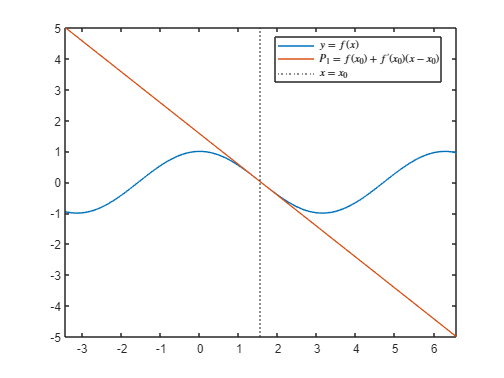

approxLabel = "$P_1 = f(x_0)+f'(x_0)(x-x_0)$";
plotWithApprox(xval,x0,@(x)F(x),@(x)P(x),approxLabel)

#### Practice Tangent Lines

Given a function, $f(x)$ and a point $x_0$, compute the tangent line to $y=f(x)$ at the point $x=x_0$. Your solution should be $P(x)$.

clear
syms F(x) dF(x) d P(x) Psoln(x) x
num = randi([-10,10]);
idx = randi(7);
opts = [1 1 1 1 2 3 4];
x0 = num/opts(idx);
[myFun,varChoice,~] = genFun(x,[1 2]);  % genProb is defined in Helper Functions   

Remember that exp(x) is the notation for e^x in MATLAB.


F(x) = myFun;
dF(x) = diff(F(x),x);
while imag(double(F(x0))) ~= 0 || imag(double(dF(x0))) ~= 0
    [myFun,varChoice,~] = genFun(x,[1 2]);  % genProb is defined in Helper Functions   
    F(x) = myFun;
    dF(x) = diff(F(x),x);
end
displayFormula("f(varChoice) = myFun")

$$f\left(x\right)=-4\,x^{6}\,{\mathrm{e}}^{2\,x}$$


xVal = x0-5:0.1:x0+5;
displayFormula("x_0 = x0")

$$x_{0}=-2$$

Psoln(x) = F(x0)+dF(x0)*(x-x0);

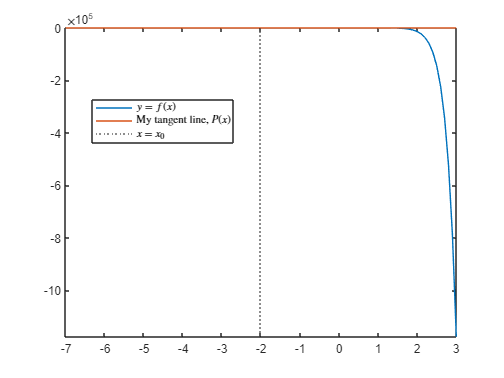

P(x) = -4*(-2)^6*exp(-4)-(24*(-2)^5*exp(-4)+4*(-2)^6*2*exp(-4))*(x+2);
 
plotWithApprox(xVal,x0,@(x)F(x),@(x)P(x),"My tangent line, $P(x)$")

checkPofx(@(x)P(x),@(x)Psoln(x),x0)

You have the correct value for f(x_0)
You have the correct value for f'(x_0)
Your solution is correct.


Consider the $n^{\text{th}}$ Taylor polynomial, $P_n(x)$, defined as:


$$P_n(x) = f(x_0) + \left. \frac{\text{d} f}{\text{d} x} \right|_{x_0} (x - x_0) + \left. \frac{\text{d}^2 f}{\text{d} x^2} \right|_{x_0} (x - x_0)^2 + \ldots + \left. \frac{\text{d}^n f}{\text{d} x^n} \right|_{x_0} (x - x_0)^n$$


## Further Exploration: Taylor Series

If we take this to the limit, and allow an infinite number of terms in our sum we have the expression:


$$f(x_0) + \sum_{i=1}^{\infty} \left.\frac{\text{d}^if}{\text{d}x^i}\right|_{x_0} (x-x_0)^i$$


In fact, for sufficiently nice functions, called *analytic functions*, this expression converges to the value of the function itself: 


$$f(x) = f(x_0) + \sum_{i = 1}^\infty \left. \frac{\text{d}^if}{\text{d}x^i} \right|_{x_0} (x - x_0)^i$$


function plotWithApprox(xval,x0,Fh,dFh,approxLabel)
clf
plot(xval,double(Fh(xval)))
hold on
plot(xval,double(dFh(xval)))
xline(x0,":")
hold off
legend(["$y=f(x)$" approxLabel "$x=x_0$"],"Interpreter","latex","Location","best")
axis tight
end

function checkPofx(Ph,Psolnh,x0)
syms x
flag = [0 0];
    if Ph(x0) - Psolnh(x0) < 4*eps
        disp("You have the correct value for f(x_0)")
        flag(1) = 1;
    end
    if double(diff(Ph(x),x)-diff(Psolnh(x),x))<4*eps
        disp("You have the correct value for f'(x_0)")
        flag(2) = 1;
    end

flag = logical(flag);

if double(diff(Psolnh(x)-Ph(x),x)) < 4*eps && flag(1)
    disp("Your solution is correct.")
else
    disp("Your solution is incorrect. Please try again.")
end
end
